**Построение графиков VSM с ногой**

Геометрические параметры

АЛГОРИТМ РАБОТЫ программы: в положении равновесия задается преднатяжение пружины, она преднатягивается, затем положение коленного сустава управляется по моменту через ПИД. Желаемое положение - синус от 0 до pi/4

clear all;
PulleyMotor.R = 8; % mm
PulleyDrum.R = 50;
distMotor2Drum = (PulleyDrum.R+PulleyMotor.R)*1.2;
B = 65;
Roller.R = 7;
C = 150;
RollerEnd.R = 10;
SpringStiff = 18;
SpringDamp = 0.1;

sigmaMax = 110;
alphaDes = 45;
%sigmaAlpha = 50; 
ratioDrumMotor = PulleyDrum.R/PulleyMotor.R;

Геометрические параметры механизма ноги

Shank.m =  -1.59+0.036*90+0.012*180; % Масса голени
Hip.m = -2.65+0.146*90+0.014*180; % Масса бедра
Load.m = 50;                       % Масса полезной нагрузки

Shank.L = 50;        % Длина голени
Hip.L = 0.25*180;  % Длина бедра

sigmaP = 0; % Можно задать от 0 до 39.6 в градусах, где 0 - мин жесткость, 39.6 - макс жесткость
motorPos = deg2rad(sigmaP) * ratioDrumMotor;


Импорт результатов из имитационной среды в воркспейс и построение графиков

clear f7 f8 f9 f10 f11 f15;
f7 = figure;
f8 = figure;
f9 = figure;
f10 = figure;
f11 = figure;
f12 = figure;
f15 = figure;

sigmaP = linspace(0, 39.6, 5);
for i = 1:size(sigmaP,2)
    
    % Defining pretension
    motorPos = deg2rad(sigmaP(i)) * ratioDrumMotor;

    out = sim('Knee_hip_MACCEPA');

    % Импорт результатов моделирования
    Spring_Torque = -out.simout.Spring_torque.Data(:,3);
    VSM_Torque = -out.simout.VSM_Torque.Data;
    human_Torque = -out.simout.tay_act.Data;
    spring_Angle = out.simout.Spring_pos.Data; % sigma
    knee_Angle = out.simout.knee_angle.Data; % alpha
    motor_Pos = out.simout.M2_pos.Data;
    motor_Torque = out.simout.M2_torque.Data;
    gravityTorque = -out.simout.gravityTorque.Data;
    time = out.tout;

    figure(f7);
    plot(rad2deg(knee_Angle), VSM_Torque, 'LineWidth', 2);
    hold on;

    figure(f15);
    plot(rad2deg(knee_Angle(50:1000)), VSM_Torque(50:1000)./knee_Angle(50:1000), 'LineWidth', 2);
    hold on;

    figure(f11);
    plot(time, VSM_Torque, 'LineStyle', '-', 'LineWidth', 2);
    hold on;

    figure(f12);
    plot(time, human_Torque, 'LineStyle', '-', 'LineWidth', 2);
    hold on;

    switch i
        case 1
            figure(f8);
            plot(time, VSM_Torque, 'LineStyle', '-', 'LineWidth', 2, 'Color','g');   
            hold on;
            plot(time, human_Torque, 'LineStyle', '-', 'LineWidth', 2, 'Color','r');
            plot(time, (VSM_Torque+human_Torque), 'LineStyle', '--', 'LineWidth', 2, 'Color','b');
            plot(time, gravityTorque, 'LineStyle', '-', 'LineWidth', 2, 'Color','k');
        case 3
            figure(f9);
            plot(time, VSM_Torque, 'LineStyle', '-', 'LineWidth', 2, 'Color','g');   
            hold on;
            plot(time, human_Torque, 'LineStyle', '-', 'LineWidth', 2, 'Color','r');
            plot(time, (VSM_Torque+human_Torque), 'LineStyle', '--', 'LineWidth', 2, 'Color','b');
            plot(time, gravityTorque, 'LineStyle', '-', 'LineWidth', 2, 'Color','k');
        case 5
            figure(f10);
            plot(time, VSM_Torque, 'LineStyle', '-', 'LineWidth', 2, 'Color','g');   
            hold on;
            plot(time, human_Torque, 'LineStyle', '-', 'LineWidth', 2, 'Color','r');
            plot(time, (VSM_Torque+human_Torque), 'LineStyle', '--', 'LineWidth', 2, 'Color','b');
            plot(time, gravityTorque, 'LineStyle', '-', 'LineWidth', 2, 'Color','k');
    end
end

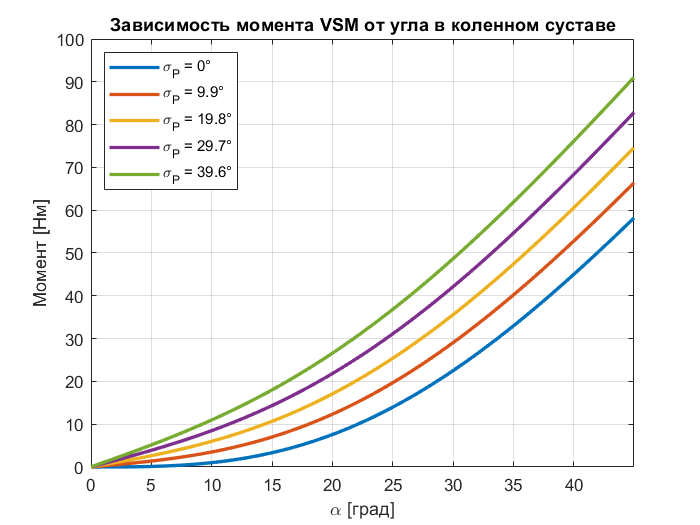



figure(f7);
xlim([0 max(rad2deg(knee_Angle))])
grid on;
sigmaP = linspace(0, 39.6, 5);
legend(strcat('\sigma_P', 32, '=', 32, num2str(round(10*sigmaP(1))/10), 176),...
       strcat('\sigma_P', 32, '=', 32, num2str(round(10*sigmaP(2))/10), 176),...
       strcat('\sigma_P', 32, '=', 32, num2str(round(10*sigmaP(3))/10), 176),...
       strcat('\sigma_P', 32, '=', 32, num2str(round(10*sigmaP(4))/10), 176),...
       strcat('\sigma_P', 32, '=', 32, num2str(round(10*sigmaP(5))/10), 176), 'Location', 'northwest');
xlabel('\alpha [град]');
ylabel('Момент [Нм]');
title('Зависимость момента VSM от угла в коленном суставе');

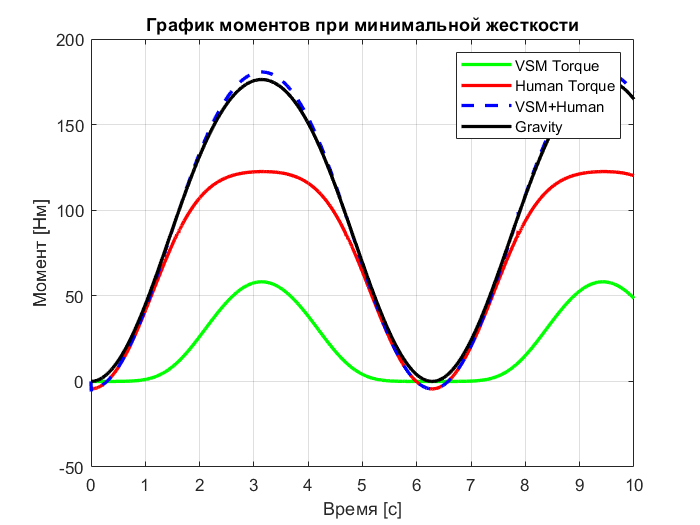


figure(f8);
grid on;
legend('VSM Torque', 'Human Torque', 'VSM+Human', 'Gravity', 'Location', 'northeast');
xlabel('Время [с]');
ylabel('Момент [Нм]');
title('График моментов при минимальной жесткости');

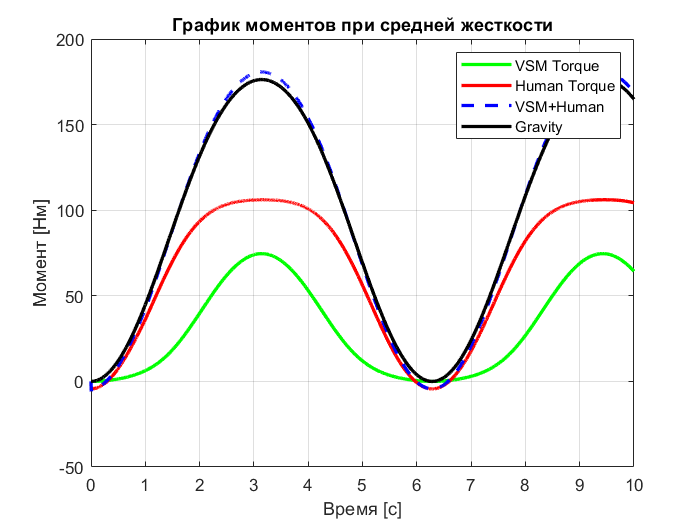


figure(f9);
grid on;
legend('VSM Torque', 'Human Torque', 'VSM+Human', 'Gravity', 'Location', 'northeast');
xlabel('Время [с]');
ylabel('Момент [Нм]');
title('График моментов при средней жесткости');

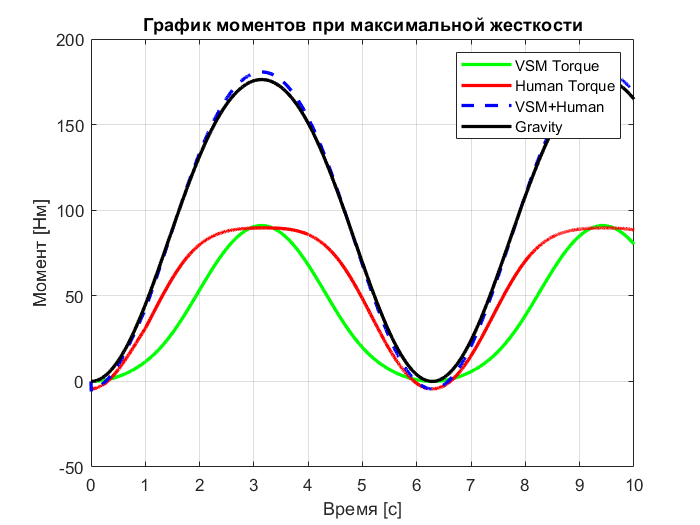


figure(f10);
grid on;
legend('VSM Torque', 'Human Torque', 'VSM+Human', 'Gravity', 'Location', 'northeast');
xlabel('Время [с]');
ylabel('Момент [Нм]');
title('График моментов при максимальной жесткости');

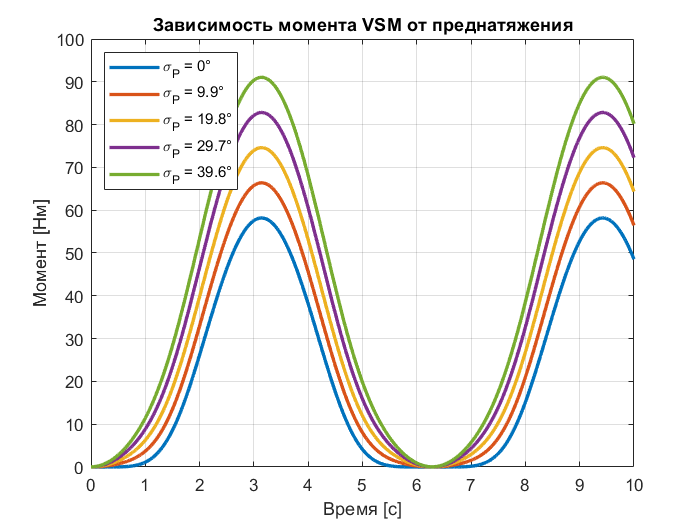


figure(f11);
grid on;
sigmaP = linspace(0, 39.6, 5);
legend(strcat('\sigma_P', 32, '=', 32, num2str(round(10*sigmaP(1))/10), 176),...
       strcat('\sigma_P', 32, '=', 32, num2str(round(10*sigmaP(2))/10), 176),...
       strcat('\sigma_P', 32, '=', 32, num2str(round(10*sigmaP(3))/10), 176),...
       strcat('\sigma_P', 32, '=', 32, num2str(round(10*sigmaP(4))/10), 176),...
       strcat('\sigma_P', 32, '=', 32, num2str(round(10*sigmaP(5))/10), 176), 'Location', 'northwest');
xlabel('Время [с]');
ylabel('Момент [Нм]');
title('Зависимость момента VSM от преднатяжения');

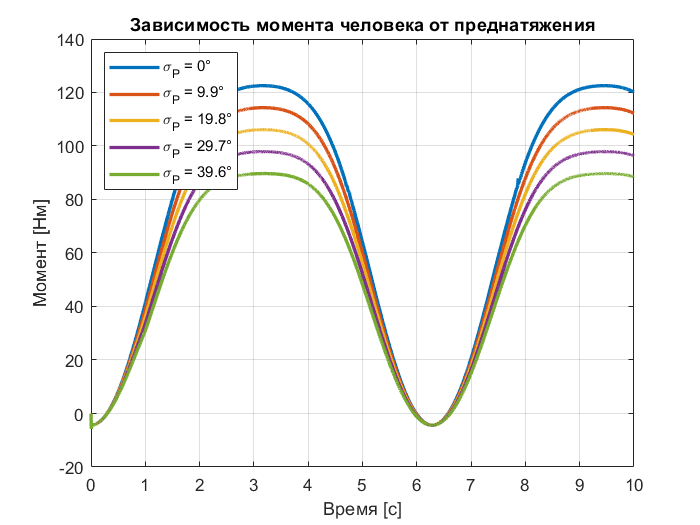


figure(f12);
grid on;
sigmaP = linspace(0, 39.6, 5);
legend(strcat('\sigma_P', 32, '=', 32, num2str(round(10*sigmaP(1))/10), 176),...
       strcat('\sigma_P', 32, '=', 32, num2str(round(10*sigmaP(2))/10), 176),...
       strcat('\sigma_P', 32, '=', 32, num2str(round(10*sigmaP(3))/10), 176),...
       strcat('\sigma_P', 32, '=', 32, num2str(round(10*sigmaP(4))/10), 176),...
       strcat('\sigma_P', 32, '=', 32, num2str(round(10*sigmaP(5))/10), 176), 'Location', 'northwest');
xlabel('Время [с]');ylabel('Момент [Нм]');
title('Зависимость момента человека от преднатяжения');

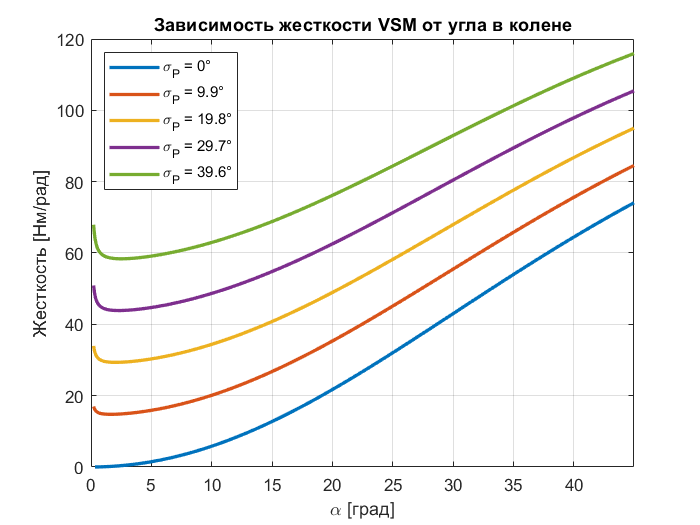


figure(f15);    
grid on;
xlim([0 max(rad2deg(knee_Angle))])
sigmaP = linspace(0, 39.6, 5);
legend(strcat('\sigma_P', 32, '=', 32, num2str(round(10*sigmaP(1))/10), 176),...
       strcat('\sigma_P', 32, '=', 32, num2str(round(10*sigmaP(2))/10), 176),...
       strcat('\sigma_P', 32, '=', 32, num2str(round(10*sigmaP(3))/10), 176),...
       strcat('\sigma_P', 32, '=', 32, num2str(round(10*sigmaP(4))/10), 176),...
       strcat('\sigma_P', 32, '=', 32, num2str(round(10*sigmaP(5))/10), 176), 'Location', 'northwest');
xlabel('\alpha [град]');
ylabel('Жесткость [Нм/рад]');
title('Зависимость жесткости VSM от угла в колене');


% Раскомментировать для сохранения графиков
% saveas(f7, 'VSM_Torque_alpha_sim_model.png');
% saveas(f8, 'Torques_time_min_stiff_sim_model.png');
% saveas(f9, 'Torques_time_middle_stiff_sim_model.png');
% saveas(f10, 'Torques_time_max_stiff_var_sim_model.png');
% saveas(f11, 'VSM_Torque_time_sim_model.png');
% saveas(f12, 'Human_Torque_time_sim_model.png');
% saveas(f15, 'VSM_Stiff_alpha_sim_model.png');